#  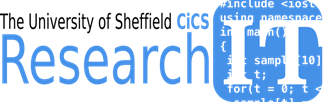                                      

# **Writing Data Analysis Programs with Matlab**

# Introduction

### Learning Outcomes

- Manipulate data sets using Matrices, Tables, Cell Arrays and Structures

- Write simple data analysis programs

- Import data into matlab

- Basic data visualisation 

- Use data analysis functions e.g. regression analysis, classification and clustering

### Sections

- Preliminary

- Importing Data

- Import Data from Single File Containing Heterogeneous Data

- Basic Statistics

- Regression Analysis

- Diagnostic Plots

- Classification Using Discrimininant Analysis

- Text Processing

Data visualisation is one of the first and most powerful methods we employ for gaining insights into data. Further methods are classification and cluster analysis methods which are applicable to categorical data. Matlab also provides tools for analysing text data. A common task in data analysis is to understand and determine the relationships within data sets,  this is challenging and there are numerous techniques. These techniques form a basis for techniques such as optimisation, machine learning and deep learning all of which are supported within Matlab.

In this introductory Matlab session we will review a number of techniques such as regression analysis, classification and text processing. The research cycle is a collaboration of project partners turning ideas into project proposals after execution of the research process results are disseminated through the publication and sharing of research outputs.

The research process is an acquisition of data presenting that as information after analysis insight and sharing this knowledge becomes a shared wisdom. 

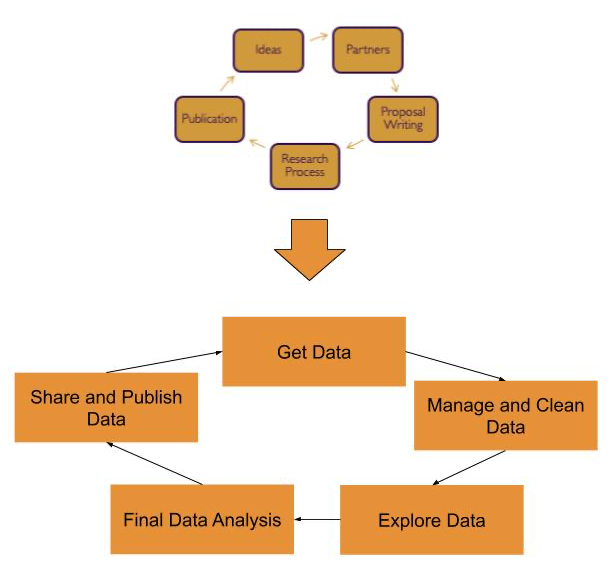

We will use a numbner of data sets to understand the research data lifecycle. Initially,  we will work with an anonymised biomedical data set from the  2007-2008 US National Health and Nutrition Examination Survey (NHANES).  The idea behind choosing this dataset is that delegates from all cultural  and language backgrounds should be able to relate to this data.  Measurements such as arm circumference, height, weight, age are  applicable to everyone. Before we import our data set we review some of the basic techniques we need to transform data into the desired form for loading into our visualisation and analysis platform.

# Preliminaries

### Matlab 

MatLab is the matrix laboratory providing tools for analysing and visualisation of data.

Users of matlab need an understanding of how to manipulate and manage data.

The basic techniques to do this are discussed in  the live script

matlab_fundamentals.mlx

%x= % 1x3 row vector elements separated with spaces
x=[1 2 3]

x =      1     2     3


%y=[] %2x1 matrix  column vector elements separated by ;
y=[sqrt(10); pi^2; sin(pi/4)]

y =     3.1623
    9.8696
    0.7071


%z=[]  % 2x3 matrix
z=[4 5 6; 7 8 9]

z =      4     5     6
     7     8     9


Functions to define array using linspace and the colon notation

u=zeros(2,2);
v=eye(3,3);
w=ones(4,4);
x1=linspace(1,10,5);
y1=(1:1:10);
z1=rand(5,1);
 % linspace(first,last,number of elements)
 %note using transpose
 
 

First create a 6x4 matrix of random numbers.

data=100*rand(6,4)

data =     9.7540   97.0593   91.5736   93.3993
   27.8498   95.7167   79.2207   67.8735
   54.6882   48.5376   95.9492   75.7740
   95.7507   80.0280   65.5741   74.3132
   96.4889   14.1886    3.5712   39.2227
   15.7613   42.1761   84.9129   65.5478



%x1= %extract  a specific element
x1=data(2,2)

x1 = 95.7167

# Importing Data

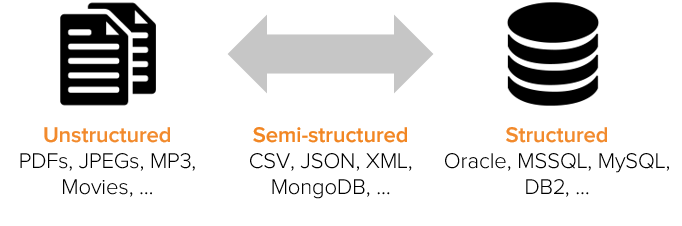

Matlab provides a range of tools for importing a variety of formats including text, spreadsheets, images, audio files, xml formats and general pupose tools for developing bespoke file readers.

One of the first methods is the save and load command which can be used to save and load workspace variables.

For example to save all the current work space variables use the command

%TODO
save('workspacevars.mat')

Error using cd
Cannot CD to /Users/mikegriffiths/Downloads/../matlab_examples/casestudies/health (Name is nonexistent or not a directory).

to save a specific variable for example the M cell array

%TODO
%save the data matrix
save('workspace-data.mat',"data")

Note variables to be saved are indicated in single quotes and there is a comma separated list of variables.

[Data Import and Export](https://uk.mathworks.com/help/matlab/data-import-and-export.html)

The simplest way to import data is to use the data import wizard provided through the matlab workbench there is a button to start the wizard on the home bar of the Matlab workbench. When the wizard starts the user is presented with a file input dialog, the dialog which follows presents a section of the input file and allows the user to set separators between each of the fields, set the number of headerlines. Data can be read in directly using the importdata command. A useful feature of the data import wizard is the script generation utility for generating a script used to import the data file. 

[importdata](https://uk.mathworks.com/help/matlab/ref/importdata.html)

# Import data from a single file containing heterogeneous data.

We will use a table to hold the results. Tables are for storing heterogeneous tabular data.

% Inspect the data file:
%first modify the path variable so that data files can be located
addpath('../data/');

%Open a data file using the editor and inspect it
edit('MedicalData.txt'); 

 

Use READTABLE to import the data. If unfamiliar with this function, this  is a good opportunity to demonstrate the use of F1/searching in the documentation. It's also worth mentioning the table of import/export functions at this point. Search for "Supported File Formats" to bring up this table in the documentation, and point out the use of the READTABLE function.

help('readtable')
%TODO
%use readtable specify tab Delimeter '\t' write data to medData
medData = readtable('MedicalData.txt','Delimiter','\t') 


Why are people so old? They're not really, it's just that Age is recorded in months. So we might want to convert the data.


% Table variables are accessed using the dot syntax (similar to structures).
medData.Age = medData.Age/12; % Note: age is recorded in months.

% Best practice would be to have comments explaining any "magic numbers" in
% the code. For example, where did the 12 come from?
% As an alternative, we could use "self-commenting" variables, e.g.
months2years = 1/12;

% Compute pulse pressure and store this as an additional table variable.
medData.BPDiff = medData.BPSyst1-medData.BPDias1;

% What about naming conventions? Generally we would use camel case.
% Table/structure variable names can be capitalised. Try to 
% agree on a convention, and then stick with it.

### Plotting vectors and annotating graphs.

How  can we visualise the information we have just computed? It's worth  showing all available plots from the Plots tab at this point.

figure % New figure.
%TODO
% Basic discrete plot and annotations.
%scatter plot medData.Age v medData.BPDiffxlabel age ylabel pressure
scatter(medData.Age,medData.BPDiff)
xlabel='Age'
ylabel='Pressure'


### Low-Level File I/O.

Suppose we have data from a file containing numeric data. How can we read this in efficiently?  Three-step process, using textscan for text files.

% The open/close statements are essential. 
% What happens if the file remains open? Why is it good practice to ensure files are
% closed after use?

fileID = fopen('HeightWaistData.txt');

% The next step is critical. This is where you can control the precise
% format MATLAB will use to import the data. See the documentation for
% textscan for more details.
dataFormat = '%f %f'; % Two columns of numeric (double, floating point) data.
heightWaistData = textscan(fileID, dataFormat, ...
    'Headerlines', 1, 'Delimiter', '\t');

fclose(fileID);

% Do we really need to use DOUBLE to store the data? How
% many significant figures are there? What else could we use to save
% memory? (SINGLE, specified via %f32 in TEXTSCAN).

### Cell Arrays.

The data from textscan is  imported as a cell array in the MATLAB workspace. The data is imported  into a 1x2 cell array (each column of data is stored in a separate  cell). A useful visualisation function for inspecting cell arrays is  CELLPLOT. This can help to alleviate misunderstanding of how cell arrays work.

figure; cellplot(heightWaistData)

### Converting Data Types.

All the elements of a MATLAB array must be the same type. This rule is particularly important when attempting to concatenate data of different types (e.g. strings  and numbers). In the documentation, you can show the reference page at:  MATLAB -> Language Fundamentals -> Data Types -> Data Type  Conversion which has a comprehensive list of conversion functions.

An ETL pipeline is a sequence of processes for obtaining data and transforming into a valid form for data analysis

Extract -> Transform->Load

Unwanted Observations

Remove Outliers

Fix Structural Errors

Handle Missing Data

Filter and Sort data

% Convert the data to a useful format.
HW = cell2mat(heightWaistData);

% Alternatively, you can show HW = [heightWaistData{1}, heightWaistData{2}]
% or even HW = [heightWaistData{:}]. However, this will require explanation
% of cell indexing (curly brackets give contents) versus standard array
% indexing (round brackets give a sub-cell array).

% Try computing the mean of each variable.
disp(mean(HW))

% Why does this not give us "proper" values? NaNs - missing data. We would
% like to remove them to obtain proper results. However, we need to know
% how to index into arrays before attempting this.

### 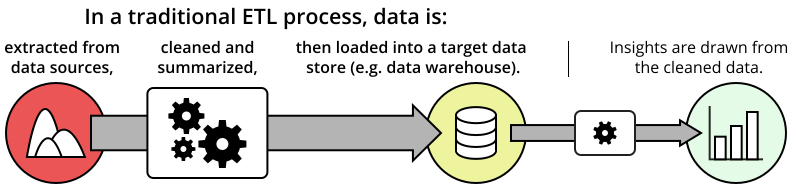

### Accessing Data in Arrays.

Data in MATLAB can be accessed using several indexing methods. Generally, row/column, or  subscript, indexing is the natural method to introduce first. Useful  tips here include the use of the "end" keyword, as well as the use of  the colon as an index as a shortcut for 1:end. Emphasise that row/column indices do not have to be scalar values.

% Extract height and waist data separately.
Height = HW(:, 1);
Waist = HW(:, 2);

### Dealing with Missing Data.

This requires use of logical indexing (passing logical arrays as indices to other  arrays). The key function here is ISNAN (it's worth showing the  reference page IS* in the documentation which has a list of all useful  functions for detecting certain conditions or states). Also, you can  show the reference page >> doc ops which has a list of all  MATLAB's operators, including logical operators which are required here.

% Remove any observations containing NaNs.
badObs = isnan(Height) | isnan(Waist);
cleanHWData = HW(~badObs, :);
disp(mean(cleanHWData))

## Importing Data from Multiple Files.

We have  seen how to import homogeneous and heterogeneous data from single files. Often, researchers have multiple data files with similar formats, so it is useful to know how to batch process a list of files. The  documentation contains a list of functions for performing file and  directory management, such as changing directory, moving files, and  creating directories: MATLAB -> Data and File Management -> File  Operations -> Files and Folders.

% The first step is to form a list of files to import data from.
% Warning: be careful here to avoid platform-dependent issues. Use of
% FILESEP is generally recommended to avoid hard-coding slashes or
% backslashes. This should recover a list of .txt files in the "ArmsLegs"
% directory.
fileInfo = dir(['ArmsLegs', filesep, '*.txt'])
fileList = {fileInfo.name}

Here, we need to  operate on each data file. We know how many data files there are, so a  for-loop is appropriate. Use ISKEYWORD to display a list of MATLAB's  programming keywords. You may want to mention other common constructs  such as if-elseif-else, try-catch, switch-case and while-loops.

## Structure Arrays.

We would like to store the name of each file (a string) as well as the  numerical data it contains (a matrix with three columns) together in the same variable. Tables are not suitable for this, because in a table all variables must have the same number of observations. We can use a  structure array instead. This allows access to the data using the same  convenient dot syntax we used for tables, but also allows storage of  mixed-size data. (However, structures have far less available  functionality associated with them than tables. For example, SORTROWS  comes with tables but not with structures.)

% You can show the loop being performed sequentially to begin with, and
% then initiate a discussion about the Code Analyzer warning that comes up.
% This should lead to a discussion about preallocation, which can be shown
% explicitly using the STRUCT function, for example. However, in this case
% it's much easier just to do the loop backwards and therefore have the
% preallocation performed implicitly.
for k = numel(fileList):-1:1
    ArmsLegs(k).FileName = fileList{k};
    ArmsLegs(k).Data = dlmread(['ArmsLegs',filesep,fileList{k}], '\t', 1, 0);
end

## Concatenation.

After reading all the data,  we would like to merge it into one variable so that we have all of the  body measurements together. It's worth spending a bit of time talking  about concatenation with square brackets [], and then mention that for  comma-separated lists, you can use VERTCAT, HORZCAT and CAT.

ALData = vertcat(ArmsLegs.Data);

## Logical Indexing.

We have seen logical  indexing above. We used it to detect and remove missing values. It is an important and widely applicable MATLAB language feature. For example,  we might want to visualise the split/separation between two different  groups in our population, e.g. males and females.

females = strcmp(medData.Sex, 'F');
figure
scatter3(ALData(females, 1), ALData(females, 2), ALData(females, 3), 'k.')
hold on % Ask what happens if we don't use HOLD here.
scatter3(ALData(~females, 1), ALData(~females, 2), ALData(~females, 3), 'g.')
hold off
xlabel('Leg Length')
ylabel('Arm Length')
zlabel('Arm Circ')
legend('Females', 'Males')

## Saving and Loading MAT-Files.

We have spent a lot of time and effort into importing our data effectively. Do we  really want to repeat this effort if we need the data again? Probably  not. You can save all the data to disk using a MAT-file (designed to  hold MATLAB data and variables). Loading from MAT-files is also faster  in general terms than running file import code. The idea is to import  the data only once, and then save it to a MAT-file for future use or  distribution to others.

% Save data to a MAT-file.
save('S01_HealthData.mat')

# Basic Statistics

Consider the car data set extracted from the 1974 *Motor Trend* US magazine, and comprises fuel consumption and 10 aspects of automobile design and performance for 32 automobiles (1973–74 models). Each column of the data table  represents the following properties.

mpgMiles/(US) gallon

cylNumber of cylinders

dispDisplacement (cu.in.)

hpGross horsepower

dratRear axle ratio

wtWeight (1000 lbs)

qsec1/4 mile time

vsEngine (0 = V-shaped, 1 = straight)

amTransmission (0 = automatic, 1 = manual)

gearNumber of forward gears

carbNumber of carburetors


data=readtable('../data/mtcars.csv')

data = 32×12 table
             Var1              mpg     cyl    disp     hp     drat     wt      qsec     vs    am    gear    carb
    _______________________    ____    ___    _____    ___    ____    _____    _____    __    __    ____    ____

    {'Mazda RX4'          }      21     6       160    110     3.9     2.62    16.46    0     1      4       4  
    {'Mazda RX4 Wag'      }      21     6       160    110     3.9    2.875    17.02    0     1      4       4  
    {'Datsun 710'         }    22.8     4       108     93    3.85     2.32    18.61    1     1      4       1  
    {'H

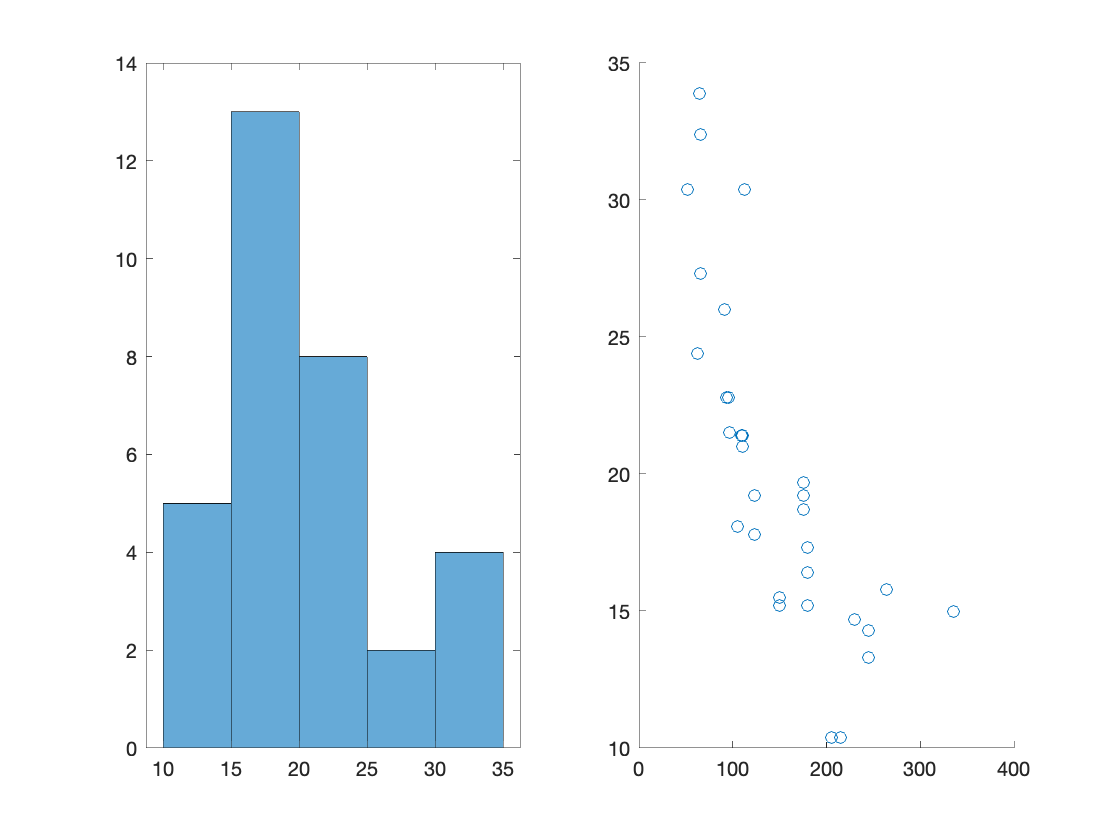

subplot(1,2,1)
histogram(data.mpg)
subplot(1,2,2)
scatter(data.hp,data.mpg)

We can easily load the data in but one of the first things we can do is to plot simple graphs displaying the relationship between different variables. We can also use statistical measures such as mean, median and mode.

- mean  - the average value of a set of numbers

- median - the middle value of a set of numbers

- mode   -  the most commonly occuring value

The histogram plot clearly verifies the modal value and the sorted table helps us to verify the median value.  As  mentioned at the start we need to undertake a fair amount of preparation or wrangling of our data before we complete our analysis.


mean(data.mpg)

ans = 20.0906

median(data.mpg)

ans = 19.2000


sort(data.mpg)

ans =    10.4000
   10.4000
   13.3000
   14.3000
   14.7000
   15.0000
   15.2000
   15.2000
   15.5000
   15.8000


mode(data.mpg)

ans = 10.4000

To other properties which we shall use are the variance and the standard deviation.

std(data.mpg)

ans = 6.0269


var(data.mpg)

ans = 36.3241

The standard deviation describes the spread of values if the standard deviation is small then the values are close to the mean value otherwise a large standard deviation indicates a larger spread about the mean. Multiplying the standard deviation by itself gives another measure of spread known as the variance.

# Regression Analysis



histogram(data.mpg)


%what kind of distribution

pdmpg = fitdist(data.mpg,'Normal')
x_values = 0:0.05:35;
y = 1400*pdf(pdmpg,x_values)/7;
plot(x_values,y,'LineWidth',2)
hold on
histogram(data.mpg)
hold off



In the following case study we will use the readtable command which creates a table by reading column oriented data from a file.

varnames=data.Properties.VariableNames

varnames=data.Properties.VariableNames;
varind=[2 4 5 6 7 8]
plotindex=1;
figure;
for i=1:6
    for j=1:6
    varnamex=varnames{varind(i)};
    varnamey=varnames{varind(j)};
    
    x=data(1:end,{varnamex});
    y=data(1:end,{varnamey});
    
    subplot(6,6,plotindex);
    scatter(table2array(x),table2array(y));
    xlabel(varnamex)
    ylabel(varnamey)
    
    plotindex=plotindex+1;
    end
end

%data=importdata('../data/field.dat')

xv=data.disp
yv=data.mpg

Least squares method

[http://mathworld.wolfram.com/LeastSquaresFitting.html](http://mathworld.wolfram.com/LeastSquaresFitting.html)



num=numel(xv);
xmean=mean(xv);
ymean=mean(yv);
sxx=sum(xv.*xv);
syy=sum(yv.*yv);
sx=sum(xv);
sy=sum(yv);

ssxx=sum((xv-xmean).*(xv-xmean));
ssyy=sum((yv-ymean).*(yv-ymean));

ssxy=sum((xv-xmean).*(yv-ymean));
b=ssxy/ssxx;

a=ymean-b*xmean;

corcoeff=ssxy.^2/(ssxx*ssyy);

xtest=50:50:400;
ytest=b.*xtest+a;
figure
hold on
plot(xtest,ytest,'x');
plot(xv,yv,'o')
hold off

To create a table from workspace variables:

`load ``carsmall`

`tbl = table(MPG,Weight);`

`tbl.Year = categorical(Model_Year);`

**Numeric Matrix for Input Data, Numeric Vector for Response**

For example, to create numeric arrays from workspace variables:

`load ``carsmall`

%data=importdata('../data/field.dat')



`X = [Weight Horsepower Cylinders Model_Year];`

`y = MPG;`

To create numeric arrays from an Excel spreadsheet:

`[X, Xnames] = xlsread(``'hospital.xls'``);`

`y = X(:,4); ``% response y is systolic pressure`

`X(:,4) = []; ``% remove y from the X matrix`

There are three ways to fit a model to data:

- [Least-Squares Fit](https://localhost:31515/static/help/stats/linear-regression-model-workflow.html#btcpwno)

- [Robust Fit](https://localhost:31515/static/help/stats/linear-regression-model-workflow.html#btcpwmd)

- [Stepwise Fit](https://localhost:31515/static/help/stats/linear-regression-model-workflow.html#btcpwm_)

%For example, to specify an interaction model using fitlm with matrix predictors:

mdl = fitlm(x,y,'interactions');


# Diagnostic Plots

Important part of data wrangling

Diagnostic plots help you identify outliers, and see other problems in your model or fit. For example, load the `carsmall` data, and make a model of `MPG` as a function of `Cylinders` (categorical) and `Weight`:

%load carsmall
%tbl = table(Weight,MPG,Cylinders);
%tbl.Cylinders = categorical(tbl.Cylinders);
%mdl = fitlm(tbl,'MPG ~ Cylinders*Weight + Weight^2');

Make a leverage plot of the data and model.

plotDiagnostics(mdllm)

There are a few points with high leverage. But this plot does not reveal whether the high-leverage points are outliers.

Look for points with large Cook’s distance.

plotDiagnostics(mdllm,'cookd')

There is one point with large Cook’s distance. Identify it and remove it from the model. You can use the Data Cursor to click the outlier and identify it, or identify it programmatically:

[~,larg] = max(mdl.Diagnostics.CooksDistance);
mdl2 = fitlm(data,'mpg ~ cyl*wt + wt^2','Exclude',larg);



### Residuals — Model Quality for Training Data

There are several residual plots to help you discover errors, outliers, or correlations in the model or data. The simplest residual plots are the default histogram plot, which shows the range of the residuals and their frequencies, and the probability plot, which shows how the distribution of the residuals compares to a normal distribution with matched variance.

Examine the residuals:

plotResiduals(mdl)

The observations above 12 are potential outliers.

plotResiduals(mdl,'probability')

The two potential outliers appear on this plot as well. Otherwise, the probability plot seems reasonably straight, meaning a reasonable fit to normally distributed residuals.

You can identify the two outliers and remove them from the data:

outl = find(mdl.Residuals.Raw > 12)

To remove the outliers, use the `Exclude` name-value pair:

mdl3 = fitlm(tbl,'MPG ~ Cylinders*Weight + Weight^2','Exclude',outl);

Examine a residuals plot of mdl2:

plotResiduals(mdl3)

The new residuals plot looks fairly symmetric, without obvious problems. However, there might be some serial correlation among the residuals. Create a new plot to see if such an effect exists.

plotResiduals(mdl3,'lagged')

The scatter plot shows many more crosses in the upper-right and lower-left quadrants than in the other two quadrants, indicating positive serial correlation among the residuals.

Another potential issue is when residuals are large for large observations. See if the current model has this issue.

plotResiduals(mdl3,'fitted')

There is some tendency for larger fitted values to have larger residuals. Perhaps the model errors are proportional to the measured values.

### Plots to Understand Predictor Effects

This example shows how to understand the effect each predictor has on a regression model using a variety of available plots. 

Examine a slice plot of the responses. This displays the effect of each predictor separately.

plotSlice(mdl)

You can drag the individual predictor values, which are represented by dashed blue vertical lines. You can also choose between simultaneous and non-simultaneous confidence bounds, which are represented by dashed red curves.

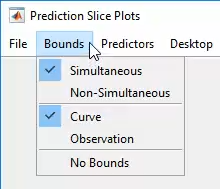

Use an effects plot to show another view of the effect of predictors on the response.

plotEffects(mdl)

This plot shows that changing `Weight` from about 2500 to 4732 lowers `MPG` by about 30 (the location of the upper blue circle). It also shows that changing the number of cylinders from 8 to 4 raises `MPG` by about 10 (the lower blue circle). The horizontal blue lines represent confidence intervals for these predictions. The predictions come from averaging over one predictor as the other is changed. In cases such as this, where the two predictors are correlated, be careful when interpreting the results.

Instead of viewing the effect of averaging over a predictor as the other is changed, examine the joint interaction in an interaction plot.

plotInteraction(mdl,'Weight','Cylinders')

The interaction plot shows the effect of changing one predictor with the other held fixed. In this case, the plot is much more informative. It shows, for example, that lowering the number of cylinders in a relatively light car (`Weight` = 1795) leads to an increase in mileage, but lowering the number of cylinders in a relatively heavy car (`Weight` = 4732) leads to a decrease in mileage.

For an even more detailed look at the interactions, look at an interaction plot with predictions. This plot holds one predictor fixed while varying the other, and plots the effect as a curve. Look at the interactions for various fixed numbers of cylinders.

plotInteraction(mdl,'Cylinders','Weight','predictions')

Now look at the interactions with various fixed levels of weight.

plotInteraction(mdl,'Weight','Cylinders','predictions')

### Plots to Understand Terms Effects

This example shows how to understand the effect of each term in a regression model using a variety of available plots.

Create an added variable plot with `Weight^2` as the added variable.

plotAdded(mdl,'Weight^2')

This plot shows the results of fitting both `Weight^2` and `MPG` to the terms other than `Weight^2`. The reason to use `plotAdded` is to understand what additional improvement in the model you get by adding `Weight^2`. The coefficient of a line fit to these points is the coefficient of `Weight^2` in the full model. The `Weight^2` predictor is just over the edge of significance (`pValue` < 0.05) as you can see in the coefficients table display. You can see that in the plot as well. The confidence bounds look like they could not contain a horizontal line (constant `y`), so a zero-slope model is not consistent with the data. 

Create an added variable plot for the model as a whole.

plotAdded(mdl)

The model as a whole is very significant, so the bounds don't come close to containing a horizontal line. The slope of the line is the slope of a fit to the predictors projected onto their best-fitting direction, or in other words, the norm of the coefficient vector. 

### Change Models

There are two ways to change a model:

- [`step`](docid:stats_ug.bszh9bd-1) — Add or subtract terms one at a time, where `step` chooses the most important term to add or remove.

- [`addTerms`](docid:stats_ug.bszh767-1) and [`removeTerms`](docid:stats_ug.bszh827-1) — Add or remove specified terms. Give the terms in any of the forms described in [Choose Model or Range of Models](docid:stats_ug.btc3kn5).

If you created a model using [`stepwiselm`](docid:stats_ug.bt0cpr2), then `step` can have an effect only if you give different upper or lower models. `step` does not work when you fit a model using `RobustOpts`.

For example, start with a linear model of mileage from the `carbig` data:

load carbig
tbl = table(Acceleration,Displacement,Horsepower,Weight,MPG);
mdl = fitlm(tbl,'linear','ResponseVar','MPG')

Try to improve the model using step for up to 10 steps:

mdl1 = step(mdl,'NSteps',10)

`step` stopped after just one change.

To try to simplify the model, remove the `Acceleration` and `Weight` terms from `mdl1`:

mdl2 = removeTerms(mdl1,'Acceleration + Weight')

`mdl2` uses just `Displacement` and `Horsepower`, and has nearly as good a fit to the data as `mdl1` in the `Adjusted R-Squared` metric.

# Classify Using Discriminant Analysis

For training data, use Fisher's sepal measurements for iris versicolor and virginica:

load fisheriris
SL = meas(51:end,1);
SW = meas(51:end,2);
group = species(51:end);
h1 = gscatter(SL,SW,group,'rb','v^',[],'off');
set(h1,'LineWidth',2)
legend('Fisher versicolor','Fisher virginica',...
       'Location','NW')

Classify a grid of measurements on the same scale:

[X,Y] = meshgrid(linspace(4.5,8),linspace(2,4));
X = X(:); Y = Y(:);
[C,err,P,logp,coeff] = classify([X Y],[SL SW],...
                                group,'Quadratic');

Visualize the classification:

hold on;
gscatter(X,Y,C,'rb','.',1,'off');
K = coeff(1,2).const;
L = coeff(1,2).linear; 
Q = coeff(1,2).quadratic;
% Function to compute K + L*v + v'*Q*v for multiple vectors
% v=[x;y]. Accepts x and y as scalars or column vectors.
f = @(x,y) K + L(1)*x + L(2)*y + Q(1,1)*x.*x + (Q(1,2)+Q(2,1))*x.*y + Q(2,2)*y.*y;
h2 = fimplicit(f,[4.5 8 2 4]);
set(h2,'Color','m','LineWidth',2,'DisplayName','Decision Boundary')
axis([4.5 8 2 4])
xlabel('Sepal Length')
ylabel('Sepal Width')
title('{\bf Classification with Fisher Training Data}')

# Processing Text

For this example we use data which has been read into text files 

matlab provides a range of tools for the import see

extractFileText

Read text from PDF, Microsoft Word, HTML, and plain text files

fileInfo = dir(['../data/soltext', filesep, '*.txt'])
fileList = {fileInfo.name}
% You can show the loop being performed sequentially to begin with, and
% then initiate a discussion about the Code Analyzer warning that comes up.
% This should lead to a discussion about preallocation, which can be shown
% explicitly using the STRUCT function, for example. However, in this case
% it's much easier just to do the loop backwards and therefore have the
% preallocation performed implicitly.
for k = numel(fileList):-1:1
    soltxt(k).FileName = fileList{k};
    soltxt(k).Data = fileread(['../data/soltext',filesep,fileList{k}]);
end


## Process the data

**Prepare Text Data for Analysis**

Create a function which tokenizes and preprocesses the text data so it can be used for analysis. The function `preprocessText`, listed at the end of the example, performs the following steps in order:

- Tokenize the text using `tokenizedDocument`.

- Lemmatize the words using `normalizeWords`.

- Erase punctuation using `erasePunctuation`.

- Remove a list of stop words (such as "and", "of", and "the") using `removeStopWords`.

- Remove words with 2 or fewer characters using `removeShortWords`.

- Remove words with 15 or more characters using `removeLongWords`.

Use the preprocessing function `preprocessText` to prepare the text data.

%documents = preprocessText(soltxt);

for i=1:5
    % Tokenize the text.
    documents = tokenizedDocument(soltxt(i).Data);
    
    % Lemmatize the words.
    documents = addPartOfSpeechDetails(documents);
    documents = normalizeWords(documents,'Style','lemma');
    
    % Erase punctuation.
    documents = erasePunctuation(documents);
    
    % Remove a list of stop words.
    documents = removeStopWords(documents);
    
    % Remove words with 2 or fewer characters, and words with 15 or greater
    % characters.
    documents = removeShortWords(documents,2);
    documents = removeLongWords(documents,15);
    
    alldocs(i)=documents;
end

Create a bag-of-words model from the tokenized documents.

for i=1:5
    bag(i) = bagOfWords(alldocs(i));

Remove words from the bag-of-words model that have do not appear more than two times in total. Remove any documents containing no words from the bag-of-words model. 

    bag(i) = removeInfrequentWords(bag(i),2);
    bag(i) = removeEmptyDocuments(bag(i));
end

Create a bag-of-words model from the tokenized documents.

bagall = bagOfWords(alldocs);

Remove words from the bag-of-words model that have do not appear more than two times in total. Remove any documents containing no words from the bag-of-words model. 

bagall = removeInfrequentWords(bagall,2);
bagall = removeEmptyDocuments(bagall)

## Visualize Topics Using Word Clouds

You can use word clouds to view the words with the highest probabilities in each topic. Visualize the first four topics using word clouds. 

figure;
for topicIdx = 1:5
    subplot(3,2,topicIdx)
    wordcloud(bag(topicIdx));
    title(fileList{topicIdx})
end

subplot(3,2,6)
wordcloud(bagall);
title("All " )

pdftotext  installed using poppler-utils package under various Linux distributions:

`# yum install poppler-utils`

OR use the following under Debian / Ubuntu Linux

`$ sudo apt-get install poppler-utils`

pdftotext syntax

`pdftotext {``PDF-file``} {``text-file``}`